Sam Kramer

ME 4724: Acoustics Engineering

October 19th, 2023

# Homework 7

%{
    This is the code that will be used to complete homework #7 and simulate
    the transmission loss calculated for mufflers.

    Sam Kramer
    October 19th, 2023
%}

% --Setup
    clear; clc; format compact; close all;

                Part 1) Reconstruct the following figure that shows transmission loss versus the nondimensional number kL.

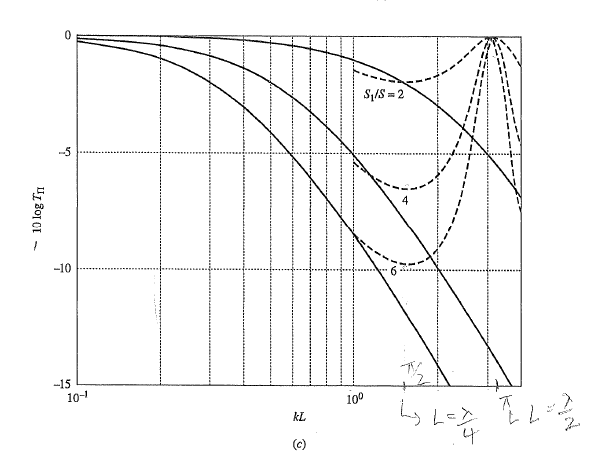

% --Parameters
    step = 0.01;
    kL = 0:step:pi;
    r1 = 0.05715;               % 2.25 in to m
    r2 = 0.125;                 % 5 in to m
    A = 80;                     % in dB
    A = (2*10^-5)*10^(A/20);    % Pa

% --Setup solutions to problem
    A_vec = A*ones([1, length(kL)]);

To solve our problem we can use matrix inversion to find the $\vec{x}$ vector. Given that we have the following system of equations:


$$\vec{A} = B\vec{x}$$


Where $\vec{A}$ is a vector of the know amplitudes of the incident wave, and the B is the coefficient matrix which is size [4x4] and $\vec{x}$ is the vector of unknows. To solve we can do:


$$B^{-1} \vec{A}= \vec{x}$$


[4x4][4x1] = [4x1]

Given that $B$ is invertable. Setting up the equation:


$$\left\lbrack \begin{array}{c}
A+B=C+D\\
{\textrm{As}}_1 -{\textrm{Bs}}_1 ={\textrm{Cs}}_2 -{\textrm{Ds}}_2 \\
C+D=E\\
{\textrm{Cs}}_2 e^{-\textrm{ikL}} -{\textrm{Ds}}_2 e^{\textrm{ikL}} ={\textrm{Es}}_1 e^{-\textrm{ikL}} 
\end{array}\right\rbrack$$


=$\left\lbrack \begin{array}{c}
A=C+D-B\\
A=\frac{{\textrm{Cs}}_2 }{s_1 }-\frac{{\textrm{Ds}}_2 }{s_1 }+B\\
0=C+D-E\\
{0=\;\textrm{Cs}}_2 e^{-\textrm{ikL}} -{\textrm{Ds}}_2 e^{\textrm{ikL}} -{\textrm{Es}}_1 e^{-\textrm{ikL}} 
\end{array}\right\rbrack$

$\left\lbrack \begin{array}{c}
A\\
A\\
0\\
0
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{c}
C+D-B\\
\frac{{\textrm{Cs}}_2 }{s_1 }-\frac{{\textrm{Ds}}_2 }{s_1 }+B\\
C+D-E\\
{\;\textrm{Cs}}_2 e^{-\textrm{ikL}} -{\textrm{Ds}}_2 e^{\textrm{ikL}} -{\textrm{Es}}_1 e^{-\textrm{ikL}} 
\end{array}\right\rbrack$

$\left\lbrack \begin{array}{c}
A\\
A\\
0\\
0
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{cccc}
-1 & 1 & 1 & 0\\
1 & \frac{s_2 }{s_1 } & \frac{-s_2 }{s_1 } & 0\\
0 & 1 & 1 & -1\\
0 & s_2 e^{-\textrm{ikL}}  & -s_2 e^{\textrm{ikL}}  & {-s}_1 e^{-\textrm{ikL}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
B\\
C\\
D\\
E
\end{array}\right\rbrack$

This is our final matrix problem that we need to solve numerically for a range of $kL$. 

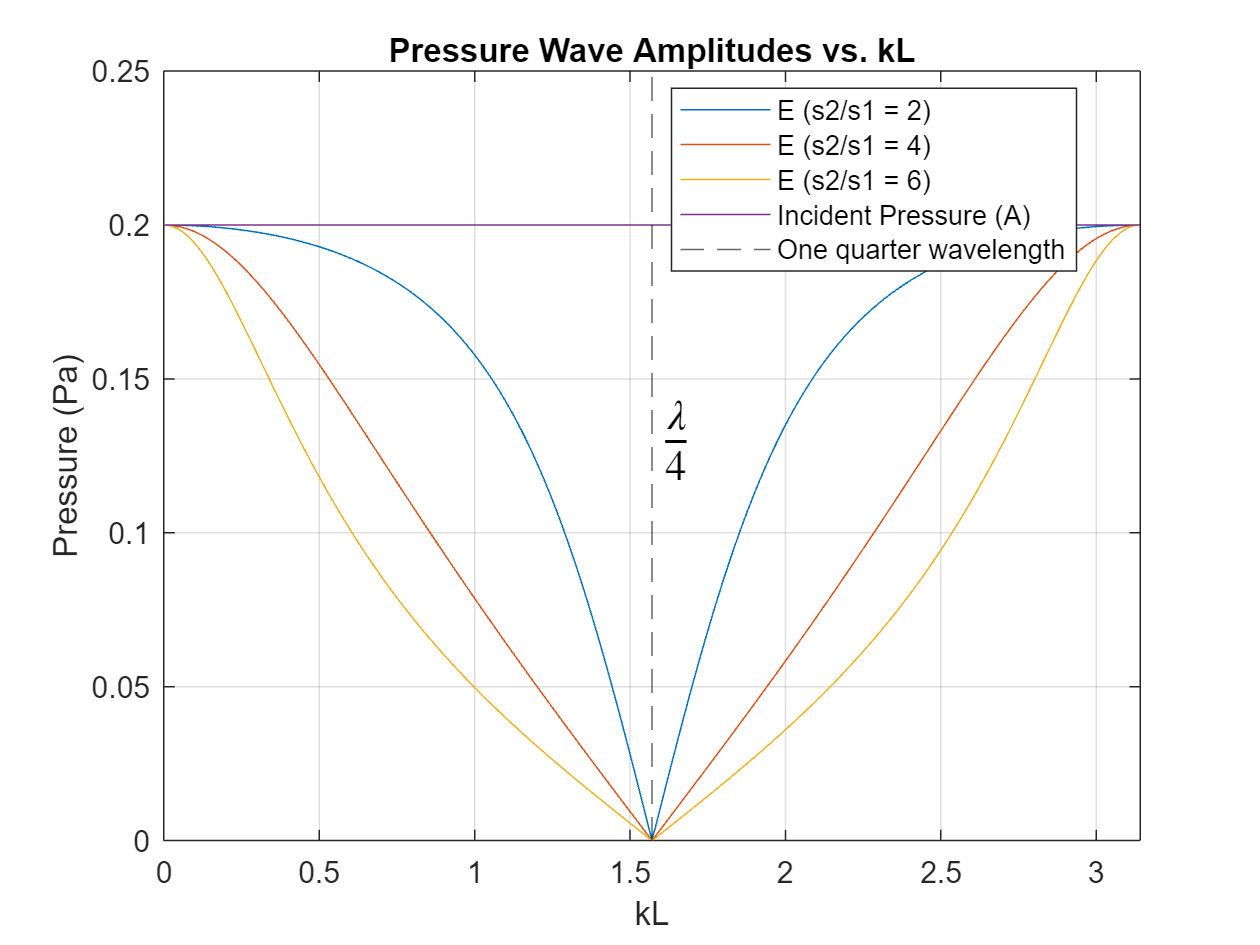

% --Problem Setup
    s1 = 1;
    s2 = [2, 4, 6];
    A = [A;
         A;
         0;
         0];
    E = [];

% --For loop for each vector
    for j = 1:length(s2)

        % --Select s
            s = s2(j);
            solutions = [];

        for i = 1:length(kL)
            
            % --Define B Matrix
                B = [-1 1 1 0;
                  1 s/s1 -s/s1 0;
                  0 1 1 -1;
                  0 s*exp(-1j *kL(i)) -s*exp(1j *kL(i)) -s1*exp(-1j *kL(i))];
    
            % --Solve
                x = inv(B)*A;
    
            % --Save solution
                solutions =[solutions abs(x)];
        end

        % --Save solution
            last_row = solutions(end,:);
            E = [E; last_row];

    end

% --Calculate pressure
    TL = 10.*log10((E./A(1)).^2);

% --Plotting E and A
    figure()
    plot(kL, E)
        hold on
    plot(kL, A_vec)
        hold on
        grid on
        xlim([0 pi])
        ylim([0 0.25])
        title('Pressure Wave Amplitudes vs. kL')
        xlabel('kL')
        ylabel('Pressure (Pa)')
        xline(pi/2,'--')
        legend('E (s2/s1 = 2)', 'E (s2/s1 = 4)', 'E (s2/s1 = 6)', 'Incident Pressure (A)','One quarter wavelength', "Position", [0.53278,0.71365,0.32143,0.19286])
        text(1.6,.13,sprintf('$$\\frac{\\lambda}{4}$$'), 'Interpreter', 'latex', 'fontsize', 14)

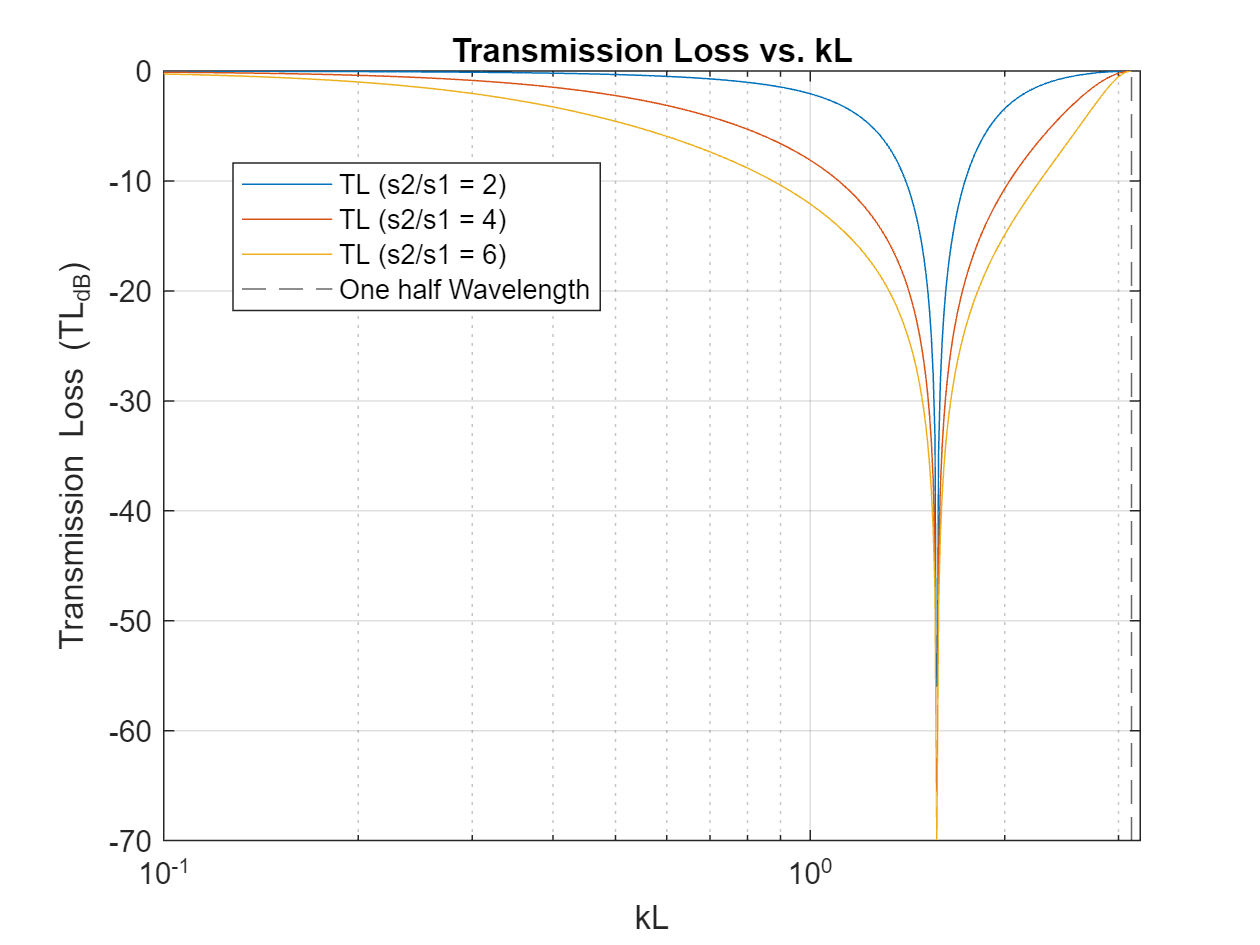

% --Plotting the solutions
    figure()
    semilogx(kL,TL)
        xlim([10^-1 pi+.1])
        grid on
        xlabel('kL')
        ylabel('Transmission Loss (TL_{dB})')
        title('Transmission Loss vs. kL')
        xline(pi,'--')
        legend('TL (s2/s1 = 2)', 'TL (s2/s1 = 4)', 'TL (s2/s1 = 6)','One half Wavelength', "Position", [0.18523,0.67165,0.29107,0.15595])

                The figure closely matches what is shown in from the notes. However, I will note that there is a large spike that occurs at $\pi/2$or one quarter wavelength. At half a wavelength, the value returns back to 0 transmission loss because we have complete constructive interference with the reflected wave. 

                Part 2) Comment on the effect of adding damping to the muffler space(S1). If you want you can mathematically estimate that by adding a loss factor to the speed of sound c in the muffler space S1 as in c*= c(1-i n) where the loss factor n=0.1 for example. Note this will make k in the muffler space complex since k= w/c. Then re-plot the curves above and see how adding damping(as in real mufflers) affects the TL. What is the advantage of adding damping? What are the disadvantages of adding damping? Normally damping would be added in real mufflers using heat resistance fiberglass. 

So now we can say that our nondimensional term kL looks like the following:


$$kL = \frac{\omega}{c(1-in)} L = \frac{\omega}{c}\frac{1}{(1-in)}L = kL \frac{1}{(1-in)}$$


We can adjust for the following change in our system by adding the adjustment term $1/(1-in)$ into the kL vector to adjust the system. We do not need to change the actual system of equations because it will be accounted for in the vector defined in the parameters section of the simulation code.

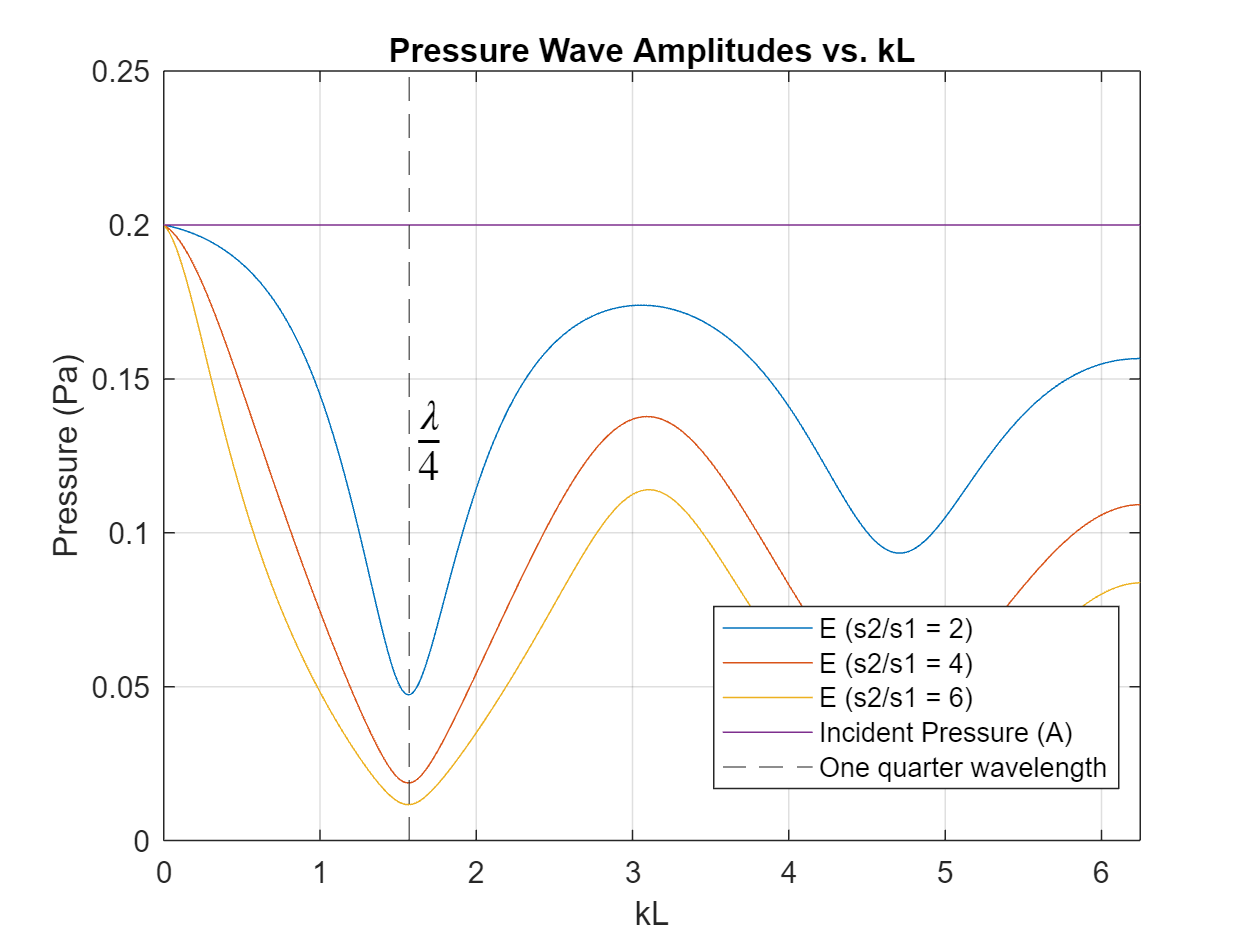

% --Parameters
    step = 0.01;
    n = 0.1;
    kL = (0:step:2*pi).*(1/(1+1i*n));       % Now equals kL times adjustment term
    r1 = 0.05715;                           % 2.25 in to m
    r2 = 0.125;                             % 5 in to m
    A = 80;                                 % in dB
    A = (2*10^-5)*10^(A/20);                % Pa

% --Setup solutions to problem
    A_vec = A*ones([1, length(kL)]);
        
% --Problem Setup
    s1 = 1;
    s2 = [2, 4, 6];
    A = [A;
         A;
         0;
         0];
    E = [];

% --For loop for each vector
    for j = 1:length(s2)

        % --Select s
            s = s2(j);
            solutions = [];

        for i = 1:length(kL)
            
            % --Define B Matrix
                B = [-1 1 1 0;
                  1 s/s1 -s/s1 0;
                  0 1 1 -1;
                  0 s*exp(-1j *kL(i)) -s*exp(1j *kL(i)) -s1*exp(-1j *kL(i))];
    
            % --Solve
                x = inv(B)*A;
    
            % --Save solution
                solutions =[solutions abs(x)];
        end

        % --Save solution
            last_row = solutions(end,:);
            E = [E; last_row];

    end

% --Calculate pressure
    TL = 10.*log10((E./A(1)).^2);

% --Plot adjusted values with damping
    figure()
    plot(abs(kL), abs(E))
        hold on
    plot(abs(kL), A_vec)
        hold on
        grid on
        max_kl = abs(kL(end));
        xlim([0 max_kl])
        ylim([0 0.25])
        title('Pressure Wave Amplitudes vs. kL')
        xlabel('kL')
        ylabel('Pressure (Pa)')
        xline(pi/2,'--')
        legend('E (s2/s1 = 2)', 'E (s2/s1 = 4)', 'E (s2/s1 = 6)', 'Incident Pressure (A)','One quarter wavelength', "Position", [0.56611,0.1655,0.32143,0.19286])
        text(1.6,.13,sprintf('$$\\frac{\\lambda}{4}$$'), 'Interpreter', 'latex', 'fontsize', 14)

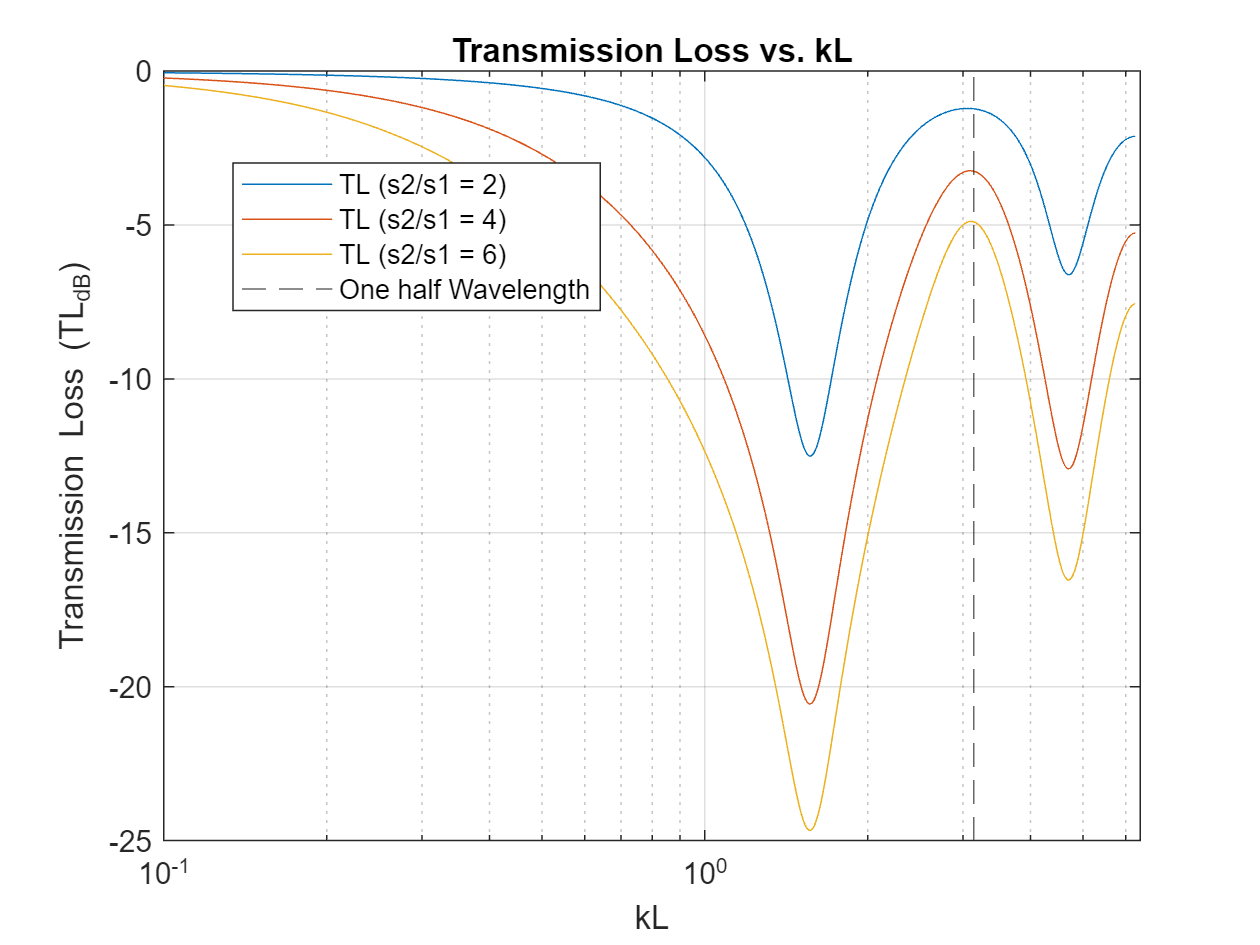

% --Plotting the solutions
    figure()
    semilogx(abs(kL),TL)
        xlim([10^-1 2*pi+.1])
        grid on
        xlabel('kL')
        ylabel('Transmission Loss (TL_{dB})')
        title('Transmission Loss vs. kL')
        xline(pi,'--')
        legend('TL (s2/s1 = 2)', 'TL (s2/s1 = 4)', 'TL (s2/s1 = 6)','One half Wavelength', "Position", [0.18523,0.67165,0.29107,0.15595])

                When we change the system to include a damping term that increases the acoustic impedence, then we can see that the peaks that are generated by the transmission loss simulations become much smaller. The peaks are also wider, which makes sense when it is a damped system. For certain frequencies around the specific frequencies that this muffler is tuned to, then we could get more favorable transmission loss. It also appears that at L = $\lambda/2$ then we get that the transmission loss peaks and the sound actually is amplified by the muffler for specific cross sectional area ratios. This could amplify certain frequencies that are present in the motor noise. We also never reach complete destructive interference of the waves because if we look in the pressure chart there is never a point where the curves reach 0 Pa. The curves do look alot closer to what is shown in the original image shown in the notes, specifically where the peaks occur, they occur alot closer to the 0 mark. 